clear; clc; close all; fclose all;

**Generate Pilot Subcarriers:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pilots for M = 2
rng default
pilot_data_m2 = randsrc(4096/4*16,1,0:2-1);
file = fopen('../Xilinx/Sw_Source/ofdm/files/PilotDataM2.txt','wt');
fprintf(file, "%d\n", pilot_data_m2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pilots for M = 4
rng default
pilot_data_m4 = randsrc(4096/4*16,1,0:4-1);
file = fopen('../Xilinx/SW_Source/ofdm/files/PilotDataM4.txt','wt');
fprintf(file, "%d\n", pilot_data_m4);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pilots for M = 16
rng default
pilot_data_m16 = randsrc(4096/4*16,1,0:16-1);
file = fopen('../Xilinx/SW_Source/ofdm/files/PilotDataM16.txt','wt');
fprintf(file, "%d\n", pilot_data_m16);
fclose('all');

**OFDM Parameters:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read OFDM Parameters from TX Frequency file header
file = fopen('../Xilinx/SW_Source/ofdm/files/TxFreqData1.txt','r');
nfft = fscanf(file,"%d,",1);
BW = fscanf(file,"%d,",1);
cp_len = fscanf(file,"%d,",1);
M = fscanf(file,"%d,",1);
ofdm_symbols = fscanf(file,"%d,",1);
tx_scale = fscanf(file,"%d,",1);
freq_data_ofdm = [];
for i = 1:nfft*ofdm_symbols
    tmp_i = fscanf(file,"%d");
    tmp_q = fscanf(file,",%d");
    tmp_iq = complex(tmp_i, tmp_q);
    freq_data_ofdm = [freq_data_ofdm tmp_iq];
end
freq_data_ofdm_1 = reshape(freq_data_ofdm,[nfft ofdm_symbols]);

pilot_density = 0.25; % Hardcoded value

**Calculated OFDM Parameters:**

rep = 1/pilot_density;
pilot_index = 1:rep:nfft;
data_index = 1:nfft;
data_index(pilot_index) = [];
scs = BW/nfft;
num_data_bits = length(data_index)*ofdm_symbols;
pilot_carriers = length(pilot_index);
data_carriers = length(data_index);
n_packed = nfft*M;

% For rest of script
rng default
pilot_data = randsrc(pilot_carriers,ofdm_symbols,0:M-1);

**QPSK Modulation:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read TX data bits
file = fopen('../Xilinx/SW_Source/ofdm/files/TxModData1.txt','r');
nfft = fscanf(file,"%d",1);
M = fscanf(file,"%d",1);
ofdm_symbols = fscanf(file,"%d",1);
data_char = fscanf(file,"%d",(data_carriers)*ofdm_symbols);
fclose('all');
data = reshape(data_char,[data_carriers ofdm_symbols]);
mod_data = data;

qpsk_mod_data = qammod(data,M);
reference_pilot = qammod(pilot_data,M);

**Insert Pilots:**

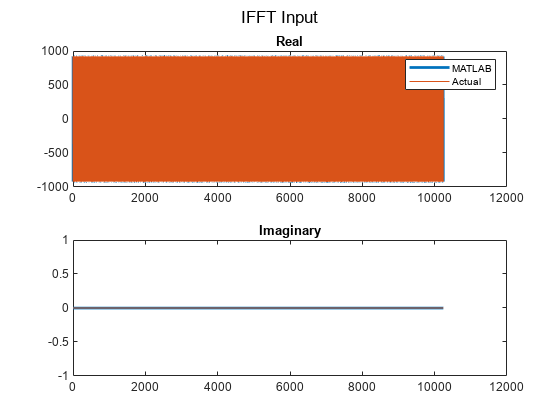

carriers = zeros(nfft,ofdm_symbols);
carriers(pilot_index,:) = reference_pilot;
carriers(data_index,:) = qpsk_mod_data;
carriers = carriers*tx_scale;

carriers_plot = reshape(carriers,[1 ofdm_symbols*nfft]);
figure(),subplot(2,1,1),plot(real(carriers_plot),'LineWidth',2),hold on,plot(real(freq_data_ofdm)),legend('MATLAB','Actual'),title('Real')
subplot(2,1,2),plot(imag(carriers_plot),'LineWidth',2),hold on,plot(imag(freq_data_ofdm)),title('Imaginary'),sgtitle('IFFT Input')

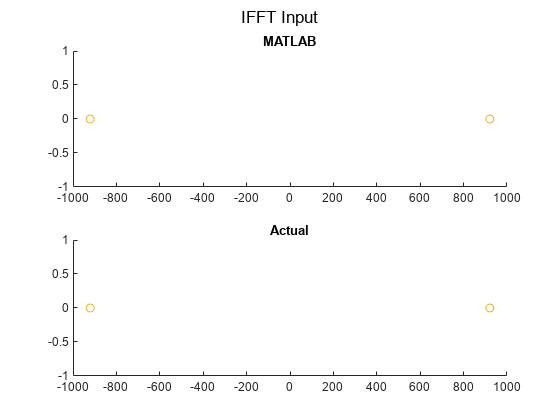

figure(),subplot(2,1,1),scatter(real(carriers),imag(carriers)),title('MATLAB')
subplot(2,1,2),scatter(real(freq_data_ofdm_1),imag(freq_data_ofdm_1)),title('Actual'),sgtitle('IFFT Input')

**Perform IFFT and CP Insertion:**

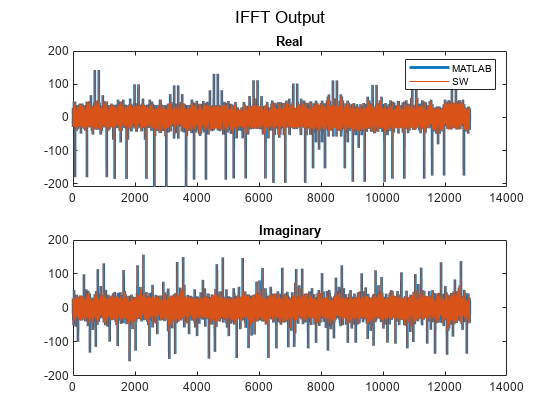

cp_start = nfft-cp_len;
ifft_sub_carriers = ifft(carriers,nfft);
cp = ifft_sub_carriers(cp_start+1:end,:);
ofdm_tx_signal_par = vertcat(cp,ifft_sub_carriers);

file = fopen('../Xilinx/SW_Source/ofdm/files/TxIfftSamples1.txt','r');
nfft_tmp = fscanf(file,"%d,",1);
ofdm_symbols_tmp = fscanf(file,"%d,",1);
cp_len_tmp = fscanf(file,"%d,",1);
if (nfft_tmp~=nfft||ofdm_symbols_tmp~=ofdm_symbols||cp_len_tmp~=cp_len)
    disp('Error with header information')
end
ifft_sw = [];
for i=1:(nfft+cp_len)*ofdm_symbols
    tmp_i = fscanf(file,"%f");
    tmp_q = fscanf(file,",%f");
    tmp_iq = complex(tmp_i, tmp_q);
    ifft_sw = [ifft_sw tmp_iq];
end
fclose('all');

ifft_sub_carriers_re = reshape(ifft_sub_carriers,[1 ofdm_symbols*(nfft)]);
ofdm_tx_signal_re = reshape(ofdm_tx_signal_par,[1 ofdm_symbols*(nfft+cp_len)]);
figure(),subplot(2,1,1),plot(real(ofdm_tx_signal_re),'LineWidth',2),hold on,plot(real(ifft_sw)),legend('MATLAB','SW'),title('Real')
subplot(2,1,2),plot(imag(ofdm_tx_signal_re),'LineWidth',2),hold on,plot(imag(ifft_sw)),title('Imaginary'),sgtitle('IFFT Output')

**Parallel to Serial:**

ofdm_tx_signal_ser = reshape(ofdm_tx_signal_par,[(nfft+cp_len)*ofdm_symbols 1]);

**Channel:**

% AWGN
ofdm_tx_signal_ch = ofdm_tx_signal_ser;

**Serial to Parallel:**

ofdm_rx_signal_par = reshape(ofdm_tx_signal_ch,[nfft+cp_len ofdm_symbols]);

**CP Removal:**

cp_rm_signal = ofdm_rx_signal_par;
cp_rm_signal(1:cp_len,:) = [];

**FFT Output:**

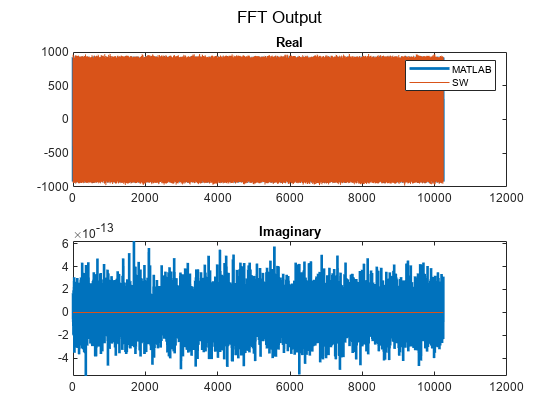

fft_signal = fft(cp_rm_signal);

file = fopen('../Xilinx/SW_Source/ofdm/files/RxFftSamples1.txt','r');
nfft_tmp = fscanf(file,"%d,",1);
ofdm_symbols_tmp = fscanf(file,"%d,",1);
cp_len_tmp = fscanf(file,"%d,",1);
if (nfft_tmp~=nfft||ofdm_symbols_tmp~=ofdm_symbols||cp_len_tmp~=cp_len)
    disp('Error with header information');
end
Fft_data_sw = [];
for i = 1:nfft*ofdm_symbols
    tmp_i = fscanf(file,"%lf");
    tmp_q = fscanf(file,",%lf");
    tmp_iq = complex(tmp_i,tmp_q);
    Fft_data_sw = [Fft_data_sw tmp_iq];
end

fft_signal_re = reshape(fft_signal,[1 ofdm_symbols*nfft]);
figure(),subplot(2,1,1),plot(real(fft_signal_re),'LineWidth',2),hold on,plot(real(Fft_data_sw)),legend('MATLAB','SW'),title('Real')
subplot(2,1,2),plot(imag(fft_signal_re),'LineWidth',2),hold on,plot(imag(Fft_data_sw)),title('Imaginary'),sgtitle('FFT Output')

**QAM Demodulation:**

file = fopen('../Xilinx/SW_Source/ofdm/files/RxDemodData1.txt','r');
nfft_tmp = fscanf(file,"%d",1);
M_tmp = fscanf(file,"%d",1);
ofdm_symbols_tmp = fscanf(file,"%d",1);
if (nfft_tmp~=nfft||M_tmp~=M||ofdm_symbols_tmp~=ofdm_symbols)
    disp('Error with header information');
end
data_char_rx = fscanf(file,"%d",(data_carriers)*ofdm_symbols);
fclose('all');

ser = symerr(data_char, data_char_rx)/numel(data_char)

ser = 0.5057